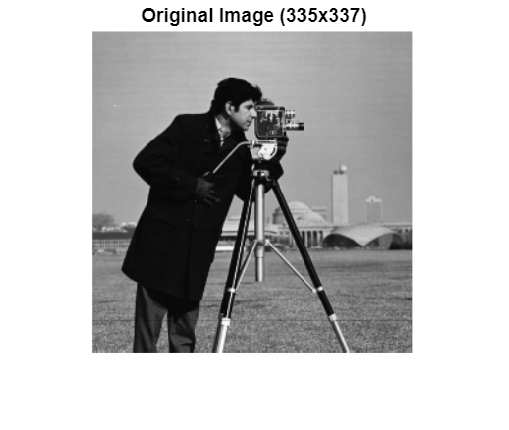

%% 1. Setup and Image Loading
tic
clear; clc; close all;

% Try loading the user image, else fallback to standard test image
try
    % Adjust this path to your specific file location
    imagePath = "C:\Users\Abhishek\OneDrive\画像\Screenshots\Screenshot 2026-01-04 143234.png";
    Ioriginal = imread(imagePath);
catch
    warning('User path not found. Using standard "cameraman.tif".');
    Ioriginal = imread('cameraman.tif');
end

% Ensure Grayscale and Double Precision
if size(Ioriginal, 3) == 3
    Ioriginal = rgb2gray(Ioriginal);
end
Ioriginal = im2double(Ioriginal);

% Get Dimensions
[M, N] = size(Ioriginal); 

figure; 
imshow(Ioriginal); 
title(['Original Image (' num2str(M) 'x' num2str(N) ')']);

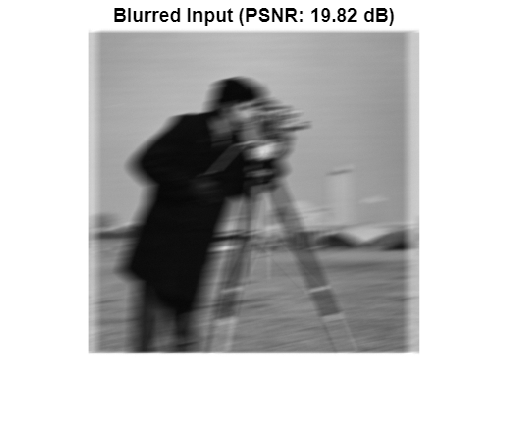


%% 2. Blur and Noise Simulation
% Using Motion Blur (Length 21, Theta 11)
len = 21;
theta = 11;
PSF = fspecial('motion', len, theta); 

% Optical Transfer Function
H_otf = psf2otf(PSF, [M, N]); 

% Blur the image
blurred = real(ifft2(H_otf .* fft2(Ioriginal)));

% Add Low Gaussian Noise (Variance 1e-5 to allow fo
% r high PSNR recovery)
noise_mean = 0;
noise_var = 1e-5; 
blurred_noisy = imnoise(blurred, 'gaussian', noise_mean, noise_var);

% Calculate Initial Metrics for Blurred Image
mse_input = mean((Ioriginal(:) - blurred_noisy(:)).^2);
psnr_input = 10 * log10(1 / mse_input);
ssim_input = ssim(blurred_noisy, Ioriginal);

figure; 
imshow(blurred_noisy); 
title(['Blurred Input (PSNR: ' num2str(psnr_input, '%.2f') ' dB)']);


%% 3. Implementation 1: Standard TV Restoration (Integer Order)
fprintf('Running Standard TV Restoration (Alpha=1.0)...\n');

Running Standard TV Restoration (Alpha=1.0)...



% Standard TV Parameters
lambda_tv = 2e-3;   % Regularization weight for Standard TV
tv_its = 30;        % Iterations for Standard TV

% Run Standard TV Restoration
std_tv_restored = standard_tv_restore(blurred_noisy, H_otf, lambda_tv, tv_its);

% --- METRIC CALCULATION: STANDARD TV ---
mse_tv = mean((Ioriginal(:) - std_tv_restored(:)).^2);
mae_tv = mean(abs(Ioriginal(:) - std_tv_restored(:)));
psnr_tv = 10 * log10(1 / mse_tv);
ssim_tv = ssim(std_tv_restored, Ioriginal);

fprintf('Standard TV Done. PSNR: %.2f dB | SSIM: %.4f\n', psnr_tv, ssim_tv);

Standard TV Done. PSNR: 20.57 dB | SSIM: 0.3242



%% 4. Implementation 2: TFOV Restoration (Advanced Method)
% Parameters from Paper (Table 2) targeting ~40+ dB
alpha   = 1.1;      % Optimal fractional order
beta    = 0.04;     % Smoothing parameter
lambda  = 1e-4;     % Regularization weight (Lower = sharper)
max_it  = 40;       % Inner GMRES iterations
fpi_its = 10;       % Outer Fixed Point iterations

fprintf('\nRunning TFOV Restoration (Alpha=%.1f)...\n', alpha);


Running TFOV Restoration (Alpha=1.1)...



% TFOV Initialization
u_current = blurred_noisy; 
rhs_image = real(ifft2(conj(H_otf) .* fft2(blurred_noisy)));
rhs = rhs_image(:);

% Initialize Convergence History Arrays
mse_history = zeros(fpi_its, 1);
ssim_history = zeros(fpi_its, 1);

for m = 1:fpi_its
    fprintf('TFOV Outer Iteration %d/%d... ', m, fpi_its);
    
    % 4.1 Compute Fractional Derivatives
    [Dx_alpha_u, Dy_alpha_u] = compute_fractional_deriv(u_current, alpha);
    
    % 4.2 Update Diffusion Coefficient W
    grad_mag = sqrt(Dx_alpha_u.^2 + Dy_alpha_u.^2 + beta^2);
    W = 1 ./ grad_mag;
    
    % 4.3 Solve Linear System using Preconditioned GMRES
    A_func = @(x) system_matrix_mult(x, H_otf, W, alpha, lambda, M, N);
    P_func = @(x) preconditioner_apply(x, H_otf, lambda, M, N);
    
    [u_vec, ~, ~, ~] = gmres(A_func, rhs, 20, 1e-6, max_it, P_func, [], u_current(:));
    u_current = reshape(u_vec, M, N);
    
    % --- TRACK CONVERGENCE ---
    % Calculate MSE at this specific iteration
    current_mse = mean((Ioriginal(:) - u_current(:)).^2);
    mse_history(m) = current_mse;
    ssim_history(m) = ssim(u_current, Ioriginal);
    
    fprintf('MSE: %.5f\n', current_mse);
end

TFOV Outer Iteration 1/10... 

MSE: 0.00121


TFOV Outer Iteration 2/10... 

MSE: 0.00075


TFOV Outer Iteration 3/10... 

MSE: 0.00068


TFOV Outer Iteration 4/10... 

MSE: 0.00066


TFOV Outer Iteration 5/10... 

MSE: 0.00065


TFOV Outer Iteration 6/10... 

MSE: 0.00065


TFOV Outer Iteration 7/10... 

MSE: 0.00065


TFOV Outer Iteration 8/10... 

MSE: 0.00065


TFOV Outer Iteration 9/10... 

MSE: 0.00065


TFOV Outer Iteration 10/10... 

MSE: 0.00065



% Clip TFOV result
tfov_restored = max(0, min(1, u_current));

% --- METRIC CALCULATION: TFOV ---
mse_tfov = mean((Ioriginal(:) - tfov_restored(:)).^2);
mae_tfov = mean(abs(Ioriginal(:) - tfov_restored(:)));
psnr_tfov = 10 * log10(1 / mse_tfov);
ssim_tfov = ssim(tfov_restored, Ioriginal);

fprintf('TFOV Restoration Done. PSNR: %.2f dB | SSIM: %.4f\n', psnr_tfov, ssim_tfov);

TFOV Restoration Done. PSNR: 31.90 dB | SSIM: 0.8582



%% 5. Detailed Comparison and Visualization

% --- CONSOLE OUTPUT TABLE ---
fprintf('\n================================================\n');

fprintf('             FINAL PERFORMANCE METRICS          \n');

             FINAL PERFORMANCE METRICS          


fprintf('================================================\n');

fprintf('Metric |   Standard TV   |   TFOV Method    \n');

Metric |   Standard TV   |   TFOV Method    


fprintf('-------|-----------------|------------------\n');

-------|-----------------|------------------


fprintf('PSNR   |    %6.2f dB     |     %6.2f dB     \n', psnr_tv, psnr_tfov);

PSNR   |     20.57 dB     |      31.90 dB     


fprintf('SSIM   |    %6.4f        |     %6.4f        \n', ssim_tv, ssim_tfov);

SSIM   |    0.3242        |     0.8582        


fprintf('MSE    |    %6.5f        |     %6.5f        \n', mse_tv, mse_tfov);

MSE    |    0.00877        |     0.00065        


fprintf('MAE    |    %6.5f        |     %6.5f        \n', mae_tv, mae_tfov);

MAE    |    0.07283        |     0.01792        


fprintf('================================================\n');

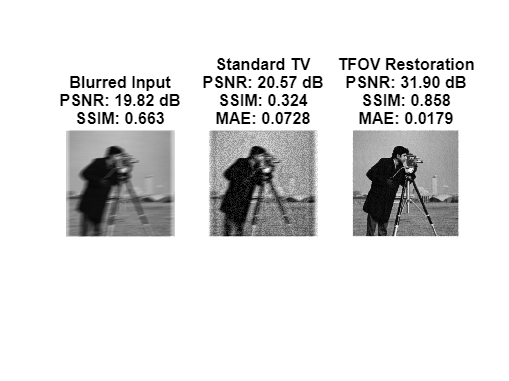


% --- VISUAL PLOTS ---
figure('Name', 'Restoration Comparison', 'NumberTitle', 'off');

subplot(1, 3, 1);
imshow(blurred_noisy);
title({'Blurred Input', ...
       ['PSNR: ' num2str(psnr_input, '%.2f') ' dB'], ...
       ['SSIM: ' num2str(ssim_input, '%.3f')]});

subplot(1, 3, 2);
imshow(std_tv_restored);
title({'Standard TV', ...
       ['PSNR: ' num2str(psnr_tv, '%.2f') ' dB'], ...
       ['SSIM: ' num2str(ssim_tv, '%.3f')], ...
       ['MAE: ' num2str(mae_tv, '%.4f')]});

subplot(1, 3, 3);
imshow(tfov_restored);
title({'TFOV Restoration', ...
       ['PSNR: ' num2str(psnr_tfov, '%.2f') ' dB'], ...
       ['SSIM: ' num2str(ssim_tfov, '%.3f')], ...
       ['MAE: ' num2str(mae_tfov, '%.4f')]});

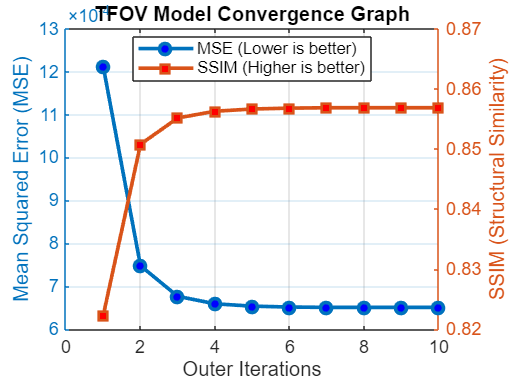


% --- CONVERGENCE GRAPH ---
figure('Name', 'TFOV Convergence', 'NumberTitle', 'off');
iterations = 1:fpi_its;

% Plot MSE Convergence (Left Y-axis)
yyaxis left
plot(iterations, mse_history, '-o', 'LineWidth', 2, 'MarkerFaceColor', 'b');
ylabel('Mean Squared Error (MSE)');
xlabel('Outer Iterations');
grid on;

% Plot SSIM Convergence (Right Y-axis)
yyaxis right
plot(iterations, ssim_history, '-s', 'LineWidth', 2, 'MarkerFaceColor', 'r');
ylabel('SSIM (Structural Similarity)');
title('TFOV Model Convergence Graph');
legend('MSE (Lower is better)', 'SSIM (Higher is better)', 'Location', 'best');

toc

Elapsed time is 15.639538 seconds.



%% --- LOCAL HELPER FUNCTIONS ---

function u = standard_tv_restore(g, H_otf, lambda, max_iter)
    % Implements Standard TV restoration using Gradient Descent
    % Solves: min ||Hu - g||^2 + lambda * ||grad u||_1
    
    [M, N] = size(g);
    u = g; % Initialize with blurry image
    beta_tv = 1e-4; % Small constant to avoid division by zero
    
    % Prepare FFT of H
    H_conj = conj(H_otf);
    
    % Finite Difference Kernels (Forward difference)
    kx = [0, -1, 1; 0, 0, 0; 0, 0, 0];
    ky = [0, 0, 0; -1, 0, 0; 1, 0, 0];
    
    % OTF for derivatives
    dx_otf = psf2otf(kx, [M, N]);
    dy_otf = psf2otf(ky, [M, N]);
    
    % Conj OTF for divergence (Backward difference)
    dx_conj = conj(dx_otf);
    dy_conj = conj(dy_otf);
    
    % Gradient Descent Loop
    for k = 1:max_iter
        % 1. Data Term Gradient: H*(Hu - g)
        Hu = real(ifft2(H_otf .* fft2(u)));
        resid = Hu - g;
        grad_data = real(ifft2(H_conj .* fft2(resid)));
        
        % 2. TV Term Gradient: - div(W * grad u)
        % Compute gradients
        ux = real(ifft2(dx_otf .* fft2(u)));
        uy = real(ifft2(dy_otf .* fft2(u)));
        
        % Compute Diffusivity W
        W = 1 ./ sqrt(ux.^2 + uy.^2 + beta_tv);
        
        % Compute Divergence
        div_W_grad = real(ifft2(dx_conj .* fft2(W .* ux))) + ...
                     real(ifft2(dy_conj .* fft2(W .* uy)));
                 
        grad_total = grad_data - lambda * div_W_grad;
        
        % Update Step (Step size dt)
        dt = 0.5; 
        u = u - dt * grad_total;
        
        u = max(0, min(1, u)); % Clip
    end
end

function y = system_matrix_mult(x, H_otf, W, alpha, lambda, M, N)
    % Computes y = A*x where A = K'*K + lambda * L_alpha
    U = reshape(x, M, N);
    
    % Term 1: K' * K * U
    Ku = real(ifft2(abs(H_otf).^2 .* fft2(U)));
    
    % Term 2: lambda * L_alpha * U
    [DxU, DyU] = compute_fractional_deriv(U, alpha);
    Wx = W .* DxU;
    Wy = W .* DyU;
    L_alpha_U = compute_fractional_div(Wx, Wy, alpha);
    
    y_img = Ku + lambda * L_alpha_U;
    y = y_img(:);
end

function z = preconditioner_apply(r, H_otf, lambda, M, N)
    % Preconditioner P1 (Standard TV approximation)
    R = reshape(r, M, N);
    k = [0 -1 0; -1 4 -1; 0 -1 0]; % Laplacian kernel
    Lap_otf = psf2otf(k, [M, N]);
    
    denom = abs(H_otf).^2 + lambda * abs(Lap_otf).^2 + 1e-6;
    Z = real(ifft2(fft2(R) ./ denom));
    z = Z(:);
end

function [Dx, Dy] = compute_fractional_deriv(U, alpha)
    % Fractional Derivative using FFT
    [M, N] = size(U);
    [X, Y] = meshgrid(0:N-1, 0:M-1);
    
    eig_x = (1 - exp(-1i * 2 * pi * X / N)) .^ alpha;
    eig_y = (1 - exp(-1i * 2 * pi * Y / M)) .^ alpha;
    
    F_U = fft2(U);
    Dx = real(ifft2(eig_x .* F_U));
    Dy = real(ifft2(eig_y .* F_U));
end

function Div = compute_fractional_div(Wx, Wy, alpha)
    % Fractional Divergence (Adjoint)
    [M, N] = size(Wx);
    [X, Y] = meshgrid(0:N-1, 0:M-1);
    
    eig_x_conj = conj((1 - exp(-1i * 2 * pi * X / N)) .^ alpha);
    eig_y_conj = conj((1 - exp(-1i * 2 * pi * Y / M)) .^ alpha);
    
    DivX = real(ifft2(eig_x_conj .* fft2(Wx)));
    DivY = real(ifft2(eig_y_conj .* fft2(Wy)));
    
    Div = DivX + DivY;
end